Symbolic computations

syms t x1 x2 real
mu = 1.5;
f = [
    x1*(1 - x1/2) - x1*x2
    x2*(mu - x2) - x1*x2
    ]

$$f = \left(\begin{array}{c} -x_{1}\,\left(\frac{x_{1}}{2}-1\right)-x_{1}\,x_{2}\\ -x_{1}\,x_{2}-x_{2}\,\left(x_{2}-\frac{3}{2}\right) \end{array}\right)$$

x = [x1;x2];
f_ode = matlabFunction(f,'Vars',{sym('t'),x})

f_ode = function_handle with value:
    @(t,in2)[-in2(1,:).*(in2(1,:)./2.0-1.0)-in2(1,:).*in2(2,:);-in2(1,:).*in2(2,:)-in2(2,:).*(in2(2,:)-3.0./2.0)]


f_rev_ode = matlabFunction(-f,'Vars',{sym('t'),x})

f_rev_ode = function_handle with value:
    @(t,in2)[in2(1,:).*(in2(1,:)./2.0-1.0)+in2(1,:).*in2(2,:);in2(1,:).*in2(2,:)+in2(2,:).*(in2(2,:)-3.0./2.0)]


Using Matlab's built-in streamslice

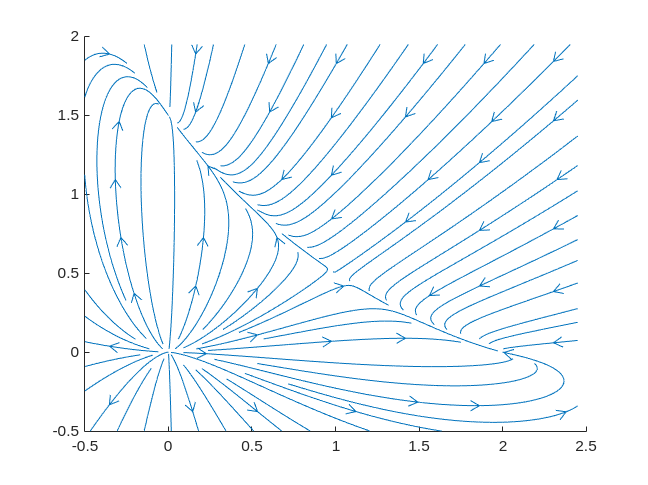

f1_fh = matlabFunction(f(1));
f2_fh = matlabFunction(f(2));

[xx1,xx2] = meshgrid(linspace(-0.5,2.45,301),linspace(-0.5,1.95,301));
ff1 = f1_fh(xx1,xx2);
ff2 = f2_fh(xx1,xx2);

fig = figure(132);
Tl = tiledlayout(1,1);
nexttile, hold on
streamslice(xx1,xx2,ff1,ff2)

Find out the equilibrium points

sol = solve(f)

sol = struct with fields:
    x1: [4×1 sym]
    x2: [4×1 sym]


Eq = [ sol.x1 , sol.x2 ]', Eq = double(Eq);

$$Eq = \left(\begin{array}{cccc} 0 & 2 & 0 & 1\\ 0 & 0 & \frac{3}{2} & \frac{1}{2} \end{array}\right)$$

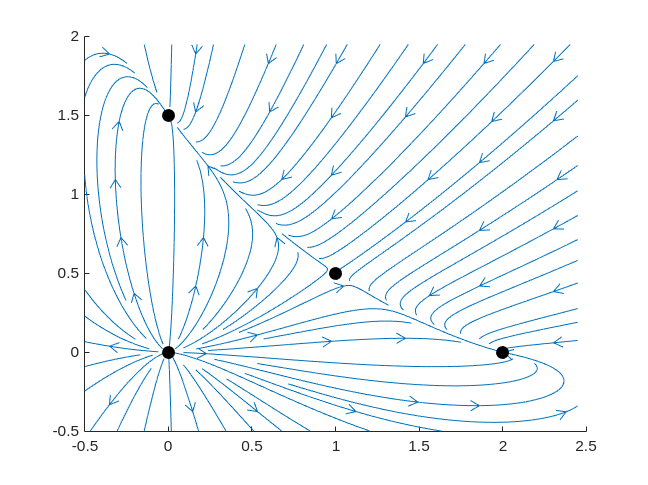

plot(sol.x1,sol.x2,'.k','MarkerSize',25)

From each equilibrium point we will draw a trajectory such that we select point close the equilibrium but displaced in the direction of a given eigenvektor. If the corresponding eigenvalue has positive real part (i.e., it is unstable), the trajectory starting at the selected point will move apart from the equilibrium showing us a specific trajectory of the system. If the eigenvalue has negative real part (i.e., it is stable), the trajectory starting very close to the equilibrium will fall back to the equilibrium (nothing interesting will happen), therefore, we draw the trajectory in a reversed time fashion. If the system is in state $x(0)$, where it was $t$ times before the current state ($x(-t) = ?$). The dynamics of the reversed time system can be derived as follows:


$$\frac{d}{dt} x(-t) = \dot x(-1) \cdot (-1) = -f(x(-t))$$


If we denote $\tau = -t$


$$\frac{d}{dt} x(\tau) = \dot x(\tau) = - f(\tau)$$


First equilibrium

Eq1 = Eq(:,1)

Eq1 =      0
     0


The Jacobian of $f(x)$:

J = jacobian(f,x)

$$J = \left(\begin{array}{cc} 1-x_{2}-x_{1} & -x_{1}\\ -x_{2} & \frac{3}{2}-2\,x_{2}-x_{1} \end{array}\right)$$

J_fh = matlabFunction(J,'Vars',{x})

J_fh = function_handle with value:
    @(in1)reshape([-in1(1,:)-in1(2,:)+1.0,-in1(2,:),-in1(1,:),-in1(1,:)-in1(2,:).*2.0+3.0./2.0],[2,2])


A1 = J_fh(Eq1)

A1 =     1.0000         0
         0    1.5000


[S1,~] = eig(A1)

S1 =      1     0
     0     1


lambda1 = eig(A1)

lambda1 =     1.0000
    1.5000


The origin is unstable.

Draw a trajectory which starts near the equilibrium

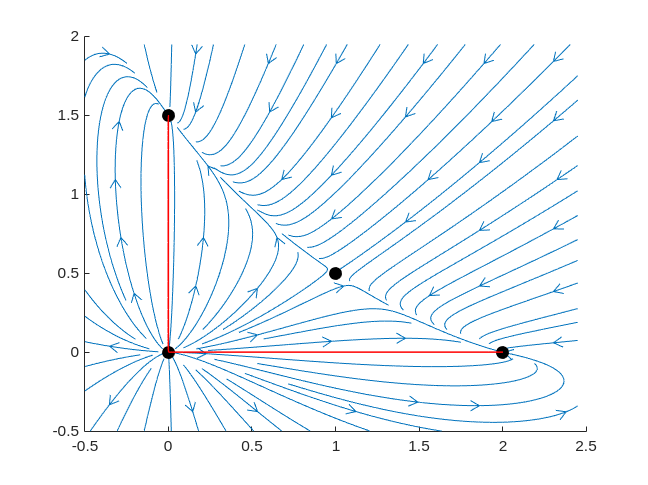

Eps = 1e-5;
[tt,xx] = ode45(f_ode,[0,100],Eq1+Eps*S1(:,1));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)
[tt,xx] = ode45(f_ode,[0,100],Eq1+Eps*S1(:,2));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)

Eq2 = Eq(:,2)

Eq2 =      2
     0


A2 = J_fh(Eq2)

A2 =    -1.0000   -2.0000
         0   -0.5000


[S2,~] = eig(A2)

S2 =     1.0000   -0.9701
         0    0.2425


lambda2 = eig(A2)

lambda2 =    -1.0000
   -0.5000


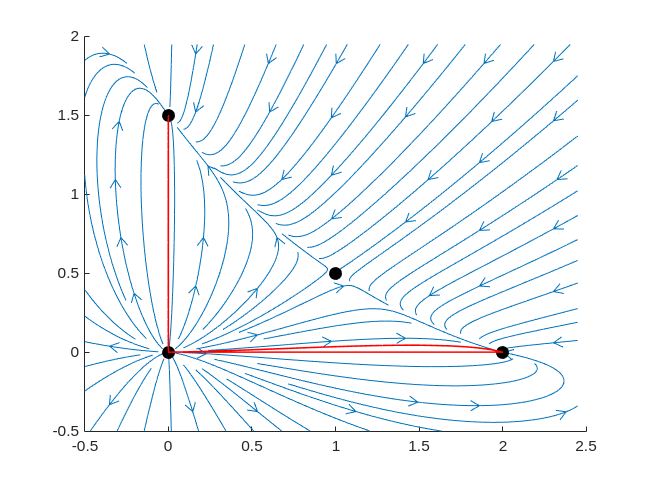

Eps = 1e-2;
[tt,xx] = ode45(f_rev_ode,[0,100],Eq2-Eps*S2(:,1));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)
[tt,xx] = ode45(f_rev_ode,[0,100],Eq2+Eps*S2(:,2));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)

Eq3 = Eq(:,3)

Eq3 =          0
    1.5000


A3 = J_fh(Eq3)

A3 =    -0.5000         0
   -1.5000   -1.5000


[S3,~] = eig(A3)

S3 =          0    0.5547
    1.0000   -0.8321


lambda3 = eig(A3)

lambda3 =    -1.5000
   -0.5000


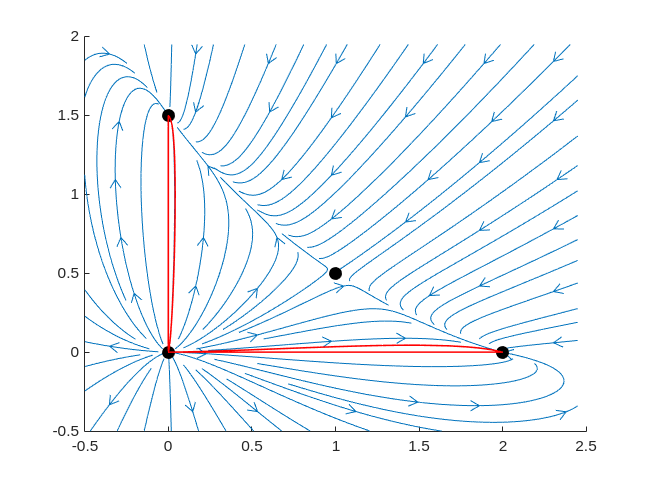

Eps = 1e-3;
[tt,xx] = ode45(f_rev_ode,[0,100],Eq3-Eps*S3(:,1));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)
[tt,xx] = ode45(f_rev_ode,[0,100],Eq3+Eps*S3(:,2));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)

Eq4 = Eq(:,4)

Eq4 =     1.0000
    0.5000


A4 = J_fh(Eq4)

A4 =    -0.5000   -1.0000
   -0.5000   -0.5000


[S4,~] = eig(A4)

S4 =     0.8165    0.8165
   -0.5774    0.5774


lambda4 = eig(A4)

lambda4 =     0.2071
   -1.2071


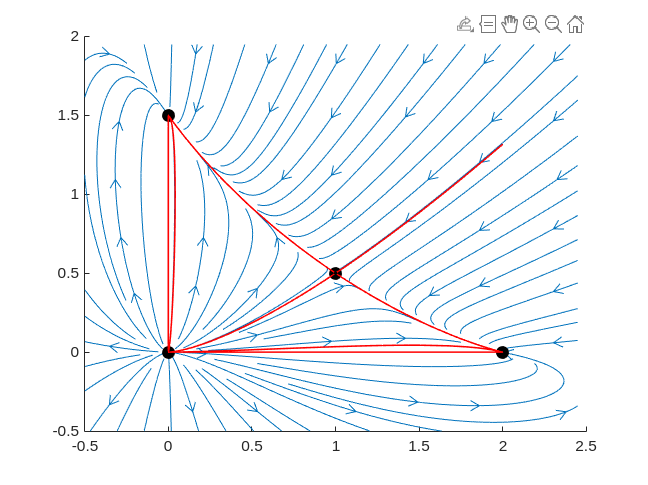

Eps = 1e-2;
[tt,xx] = ode45(f_ode,[0,100],Eq4+Eps*S4(:,1));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)
[tt,xx] = ode45(f_ode,[0,100],Eq4-Eps*S4(:,1));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)
[tt,xx] = ode45(f_rev_ode,[0,100],Eq4-Eps*S4(:,2));
plot(xx(:,1),xx(:,2),'r','LineWidth',1)

x1lim = [0 2];
x2lim = [0 1.6];
term_event = @(t,x) hp_ode_termevent_rectangle(t,x,x1lim,x2lim);
odeopts = odeset('Events',term_event);
[tt,xx] = ode45(f_rev_ode,[0,100],Eq4+Eps*S4(:,2),odeopts); % what would happen without the terminal event?
plot(xx(:,1),xx(:,2),'r','LineWidth',1)